%This Model by Bradley Sutton, PhD, at the University of Illinois,and
%modified by Claude Lieber, MD, FGCU
%has been adapted from the MATLAB code presented in Hoppensteadt and Peskin 
%"Modeling and Simulation in Medicine and the Life Sciences"

clear
close all
clc

%Time parameters 
T = 0.0125;  % Duration of heartbeat: 0.0125 min = 1 cycle
Ts = 0.4*T;  % Duration of systole: 40% of cycle       
dt = .00005*T; %This choice implies 20,000 time steps per cycle
Beats=16*T;    % 16 heart beats displayed per model runtime
%Compliance and resistance parameters. Note that valve resistances are not
%supposed to be realistic, just small enough to be negligible
Csa = .00175;  %Systemic arterial compliance: L/mmHg, original=0.0175
Rs = 17.28;    %Systemic resistance: mmHg/(L/min) - initial value 17.28
Rmi =0.01;     %mitral valve resistance: mmHg/(L/min) - initial value 0.01
RAo =0.01;     %Aortic valve resistance: mmHg/(L/min) - initial value 0.01
AoBkflo=0;     % No regurgitation       
Vlvd = .027;   %Left ventricular volume when PLV=0 (Residual volume) 
Vsad = .825;   %Systemic arterial volume when Psa = diastolic press. 
Pla = 5;       %Left atrial pressure:  mmHg Initially 5 mmHg
               %This is an mean pressure value for left atrium

%Parameters for Clv(t)
CLVD =0.0150;     %Max (diastolic) value of CLV: L/mmHg Initially 0.0146 
CLVS = 5e-5;      %Min (systolic) value of CLV: L/mmHg initially 5e-5
tauS = .0025;     %CLV time constant during systole: min (0.0025)
tauD = .005;      %CLV time constant during diastole: min (0.001)

%Initialization parameters
Plvi = 5;         %Initial value of Plv: mmHg
Psai = 80;        %initial value of Psa: mmHg (diastolc blood pressure)


Cycle=T/dt;
Syst=Ts/dt;
Diastole=Cycle-Syst;
sim('Cardio_SA_LV')
fprintf('Normal end-systolic compliance = %0.05f L/mmHg\n\n',CLVS)

Normal end-systolic compliance = 0.00005 L/mmHg



fprintf('Normal end-distolic compliance = %0.8f L/mmHg\n\n',CLVD)

Normal end-distolic compliance = 0.01500000 L/mmHg



fprintf('Normal end systolic elastance = %5.0f mmHg/L\n\n',1/CLVS)

Normal end systolic elastance = 20000 mmHg/L



fprintf('Normal end diastolic elastance = %2.2f mmHg/L\n\n',1/CLVD)

Normal end diastolic elastance = 66.67 mmHg/L





t=BloodFlows.time;

figure('color','white')
plot(VLV(300000:end),PLV(300000:end),'linewidth',2,'Color','b');
title('Normal Cardiac Cycle','FontSize',18,'FontWeight','bold')
xlabel('Ventricular Volume - Liters','FontSize',14)
ylabel('Ventricular Pressure - mm Hg','FontSize',14)
axis([0.01 max(VLV)+0.01 0 max(PLV)+10])
hold on


EDV = VLV(end);
ESV = VLV(end-Diastole+1);
SV = EDV-ESV; 
HR = 1/T;
CO = HR*SV;
fprintf('Normal Cardiac Output = %1.2f liters/min \n\n',CO)

Normal Cardiac Output = 5.31 liters/min 



SV = 1e3*SV; % converts S.V. from l/beat to ml/beat
fprintf('Normal Stroke Volume = %2.1f ml/beat \n\n',SV)

Normal Stroke Volume = 66.4 ml/beat 




% Work is calculated by numerical intergration during systole using 
    % trapazoidal technique. The average of 2 successive ventricular volumes
    %  times the difference in pressure between them (delta P)
    %  gives the area of each trapazoid
deltaP=diff(PLV(end-Cycle:end-Diastole)); % each element in this array is the 
    % difference in pressure between 2 successive ventricular pressures during
    % systole
    
SumV=(VLV(end-Cycle:end-Diastole-1)+VLV(end-Cycle+1:end-Diastole))/2; 
    % Each element of this array is the sum of two successive volumes during 
    % systole divided by 2
    % work done at each element k is deltP*(Vk+Vk+1)/2
    W=sum(deltaP.*SumV); % Work in mmHg*L - N.B. the "dot multiplication"
    W=0.1333*W; % converts W from mmHg*L to joules

fprintf('Press.*Vol. Work per Stroke (per heartbeat) = %2.4f joules/beat\n\n',W)

Press.*Vol. Work per Stroke (per heartbeat) = 1.2045 joules/beat



fprintf('Press.*Vol. Work per min. = %2.4f joules/min\n\n',HR*W)

Press.*Vol. Work per min. = 96.3588 joules/min



fprintf('Arterial pressure = %3.0f/%3.0f mmHg \n\n', ...
    max(PSA(end-Cycle:end)),min(PSA(end-Cycle:end)))

Arterial pressure = 104/ 77 mmHg 



fprintf('Ventricular pressure = %3.0f/%3.0f mmHg \n\n', ...
     max(PLV(end-Cycle:end)),min(PLV(end-Cycle:end)))

Ventricular pressure = 105/  5 mmHg 



% fprintf('Normal end diastolic elastance = %2.2f \n',1/CLVD)
% fprintf('Normal end systolic elastance = %5.2f \n',1/CLVS)

% Simulating aortic stenosis and compensation

Ks=CLVS*max(PLV(end-Cycle:end))% defines the proportionality constant

Ks = 0.0052

                                 %for systole
Kd=CLVD*max(PLV(end-Cycle:end))% for diastole

Kd = 1.5684




RAo=1;

CLVD_new=0;
CLVS_new=0;
for k=1:10 
    CLVD=(CLVD+CLVD_new)/2;% Averages the new compliances with the old ones
    CLVS=(CLVS+CLVS_new)/2;
    sim('Cardio_SA_LV')
    CLVS_new=Ks/max(PLV(end-Cycle:end));%Recalculates the compliances based on
                                    % new ventricular pressures
    CLVD_new=Kd/max(PLV(end-Cycle:end));
end

% %% Find New Left Atrial Pressure to Restore Stroke Volume and Cardiac Output
% SV_target = SV; % Target stroke volume from the normal condition
% Pla_step = 0.2; % Incremental step for left atrial pressure
% 
% % Loop to find the required Pla
% for Pla_new = Pla:Pla_step:30
%     assignin('base', 'Pla', Pla_new);
% 
%     % Run simulation
%     sim('Cardio_SA_LV');
% 
%     % Calculate stroke volume
%     EDV = VLV(end);
%     ESV = VLV(end-Diastole+1);
%     SV_current = EDV - ESV;
%     CO_current = SV_current * HR;
% 
%     % Display progress
%     fprintf('Pla = %.2f mmHg, SV = %.3f L, CO = %.3f L/min\n', Pla_new, SV_current, CO_current);
% 
%     % Check if stroke volume and cardiac output are restored
%     if abs(SV_current - SV_target) < 0.001 && abs(CO_current - CO) < 0.001
%         fprintf('Required left atrial pressure to restore SV and CO: %.2f mmHg\n', Pla_new);
%         break;
%     end
% end

Pla = 5.00 mmHg, SV = 0.058 L, CO = 4.639 L/min
Pla = 5.20 mmHg, SV = 0.060 L, CO = 4.825 L/min
Pla = 5.40 mmHg, SV = 0.063 L, CO = 5.010 L/min
Pla = 5.60 mmHg, SV = 0.065 L, CO = 5.196 L/min
Pla = 5.80 mmHg, SV = 0.067 L, CO = 5.381 L/min
Pla = 6.00 mmHg, SV = 0.070 L, CO = 5.567 L/min
Pla = 6.20 mmHg, SV = 0.072 L, CO = 5.753 L/min
Pla = 6.40 mmHg, SV = 0.074 L, CO = 5.938 L/min
Pla = 6.60 mmHg, SV = 0.077 L, CO = 6.124 L/min
Pla = 6.80 mmHg, SV = 0.079 L, CO = 6.309 L/min
Pla = 7.00 mmHg, SV = 0.081 L, CO = 6.495 L/min
Pla = 7.20 mmHg, SV = 0.084 L, CO = 6.681 L/min
Pla = 7.40 mmHg, SV = 0.086 L, CO = 6.866 L/min
Pla = 7.60 mmHg, SV = 0.088 L, CO = 7.052 L/min
Pla = 7.80 mmHg, SV = 0.090 L, CO = 7.237 L/min
Pla = 8.00 mmHg, SV = 0.093 L, CO = 7.423 L/min
Pla = 8.20 mmHg, SV = 0.095 L, CO = 7.608 L/min
Pla = 8.40 mmHg, SV = 0.097 L, CO = 7.794 L/min
Pla = 8.60 mmHg, SV = 0.100 L, CO = 7.980 L/min
Pla = 8.80 mmHg, SV = 0.102 L, CO = 8.165 L/min
Pla = 9.00 mmHg, SV = 0.104 L, CO = 8.35


fprintf('        Aortic Stenosis After Complete Compensation\n')

        Aortic Stenosis After Complete Compensation


fprintf('------------------------------------------------------------\n\n')

------------------------------------------------------------




for k=1:10 % for/loop to compensate the atrial pressure
    Pla=Pla+0.2; 
    sim('Cardio_SA_LV')
    if max(PSA(end-T/dt:end))>=100
        break
    end
end
EDV=VLV(end);
ESV=VLV(end-Diastole);
SV=EDV-ESV;
CO=SV*HR;

fprintf('End-diastolic compliance = %0.5f L/mmHg\n\n',CLVD)

End-diastolic compliance = 0.01290 L/mmHg



fprintf('End-systolic compliance = %0.9f L/mmHg\n\n',CLVS)

End-systolic compliance = 0.000043003 L/mmHg



fprintf('Compensated end diastolic elastance = %2.2f mmHg/L \n',1/CLVD)

Compensated end diastolic elastance = 77.51 mmHg/L 


fprintf('Compensated end systolic elastance = %5.2fmmHg/L \n',1/CLVS)

Compensated end systolic elastance = 23254.10mmHg/L 


fprintf('Compensated mean atrial pressure = %2.3f mmHg\n\n',Pla)

Compensated mean atrial pressure = 30.200 mmHg



EDV = VLV(end);
ESV = VLV(end-Diastole);
SV = EDV-ESV; %This renders stroke volume as 0.0645 l/beat
HR = 1/T;
CO = HR*SV;
fprintf('Cardiac Output = %1.2f liters/min \n\n',CO)

Cardiac Output = 28.02 liters/min 



SV = 1e3*SV; % converts S.V. from l/beat to ml/beat
fprintf('Stroke Volume = %2.1f ml/beat \n\n',SV)

Stroke Volume = 350.3 ml/beat 




% Work is calculated by numerical intergration during systole using 
    % trapazoidal technique. The average of 2 successive ventricular volumes
    %  times the difference in pressure between them (delta P)
    %  gives the area of each trapazoid
deltaP=diff(PLV(end-Cycle:end-Cycle+Syst)); % each element in this array is the 
    % difference in pressure between 2 successive ventricular volumes. During
    % systole
    
SumV=(VLV(end-Cycle:end-Cycle+Syst-1)+VLV(end-Cycle+1:end-Cycle+Syst))/2; 
    % Each element of this array is the sum of two successive volumes during 
    % systole divided by 2
    % work done at each element k is deltP*(Vk+Vk+1)/2
    Wn=sum(deltaP.*SumV); % Work in mmHg*L
    
    Wn=0.1333*Wn; % converts W from mmHg*L to joules
fprintf('Press.*Vol. Work per Stroke (per heartbeat) = %2.4f joules/beat\n\n',Wn)

Press.*Vol. Work per Stroke (per heartbeat) = 33.1918 joules/beat



fprintf('Press.*Vol. Work per min.  = %2.4f joules/min\n\n',HR*Wn)

Press.*Vol. Work per min.  = 2655.3445 joules/min



fprintf('%% increase in work/min after compensation for stenosis = %2.2f%%\n\n', ...
    100*(Wn)/W)

% increase in work/min after compensation for stenosis = 2755.68%



fprintf('Arterial pressure  = %3.0f/%2.0f mmHg \n\n', ...
    max(PSA(end-Cycle:end)),min(PSA(end-Cycle:end)))

Arterial pressure  = 554/406 mmHg 



fprintf('Ventricular pressure  = %3.0f/%1.0f mmHg \n\n', ...
    max(PLV(end-Cycle:end)),min(PLV(end-Cycle:end)))

Ventricular pressure  = 734/29 mmHg 



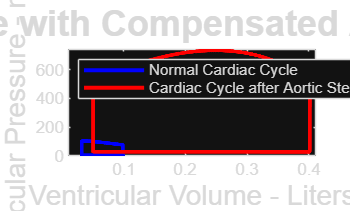



% figure('color','white')
plot(VLV(300000:end),PLV(300000:end),'linewidth',2,'Color','r');
title('Cardiac Cycle with Compensated Aortic Stenosis','FontSize',18,'FontWeight','bold')
xlabel('Ventricular Volume - Liters','FontSize',14)
ylabel('Ventricular Pressure - mm Hg','FontSize',14)
axis([0.01 max(VLV)+0.01 0 max(PLV)+10])
legend('Normal Cardiac Cycle', 'Cardiac Cycle after Aortic Stenosis', Location='northwest')
hold off


AorticArea =CO/sqrt(max(PLV)-max(PSA));
fprintf('\nAortic Cross-Sectional Area (Hakki) = %1.2f cm^2 \n\n',AorticArea)


Aortic Cross-Sectional Area (Hakki) = 2.09 cm^2 

